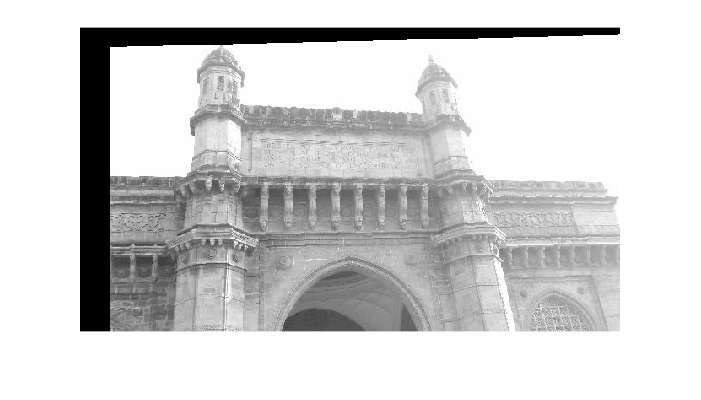

im1 = double(imread(".\HW1/goi1.jpg"));
im2 = double(imread(".\HW1/goi2_downsampled.jpg"));
%for i=1:12, figure(1); imshow(im1/255); [x1(i), y1(i)] = ginput(1);
%figure(2); imshow(im2/255); [x2(i), y2(i)] = ginput(1);
%end
x1 = [132,373,280,52,518,265,129,390,247,94,421,375];
x1 = double(x1);
y1 = [3.0000,25.0000,254.0000,278.0000,300.0000,84.0000,42.0000,65.0000,282.0000,89.0000,108.0000,235.0000];
x2 = [172,416,314,92,573,303,168,432,283,136,465,417];
x2 = double(x2);
y2 =[27.0000,38.0000,274.0000,296.0000,320.0000,100.0000,67.0000,74.0000,303.0000,114.0000,119.0000,250.0000];


A = double(zeros(3,3,4));
%for i=0:3
%    I2=[[x2(3*i+1),x2(3*i+2),x2(3*i+3)];[y2(3*i+1),y2(3*i+2),y2(3*i+3)];[1,1,1]];
%    I1=[[x1(3*i+1),x1(3*i+2),x1(3*i+3)];[y1(3*i+1),y1(3*i+2),y1(3*i+3)];[1,1,1]];
%    A(:,:,i+1)=mtimes(I2,pinv(I1));
%end
ones1 = double(zeros(1,12)+1);
P1 = [x1;y1;ones1];
P2 = [x2;y2;ones1];
T = (P2*(transpose(P1)))*(pinv((P1)*(transpose(P1))));
Tinv = pinv(T);

%Nearest neighbor interpolation
s=size(im1);
imnew=double(zeros(s(1),s(2)));

for i=1:s(1)
    for j=1:s(2)
        w = Tinv*[j;i;1];
        [min_val,min_index] = min([w(1,1)-floor(w(1,1)), ceil(w(1,1)-w(1,1))]);
        if(min_index == 1)
            w(1,1) = floor(w(1,1));
        else
            w(1,1) = ceil(w(1,1));
        end
        [min_val1,min_index1] = min([w(2,1)-floor(w(2,1)), ceil(w(2,1)-w(2,1))]);
        if(min_index1 == 1)
            w(2,1) = floor(w(2,1));
        else
            w(2,1) = ceil(w(2,1));
        end
        if(~(w(1,1)<1 || w(1,1)>s(2) || w(2,1)<1||w(2,1)>s(1)))
            imnew(i,j) = im1(w(2,1), w(1,1));
        end
    end
end
imshow(imnew/255);

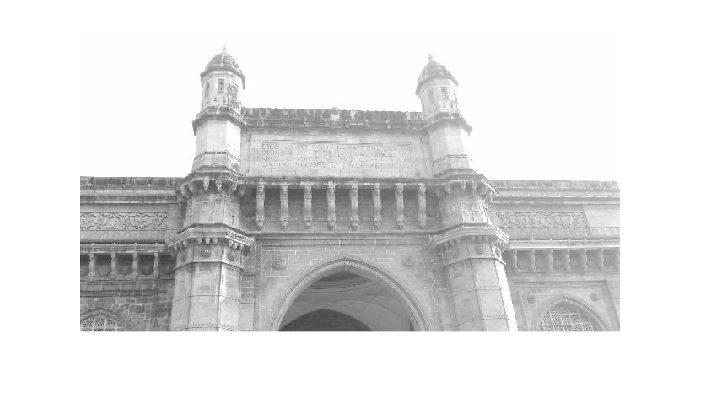

imshow(im2/255);

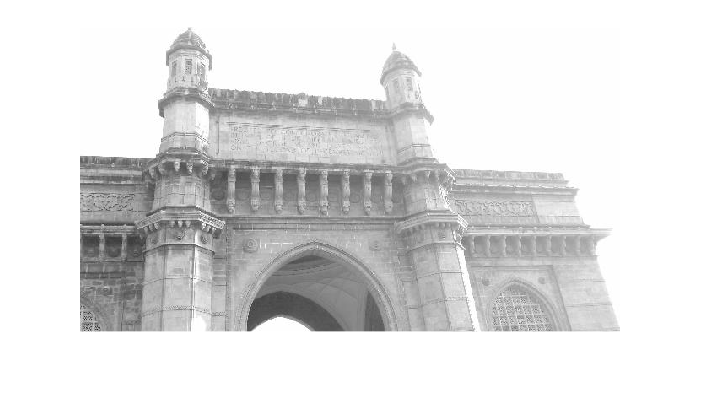

imshow(im1/255);

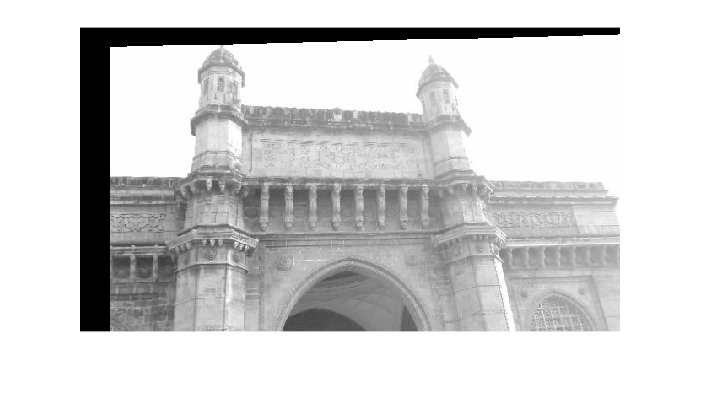


%Bilinear Interpolation
imnew2 = double(zeros(s(1), s(2)));
for i=1:s(1)
    for j=1:s(2)
        w = Tinv*[j;i;1];
        x=w(1,1);
        y=w(2,1);
        A = (x-floor(x))*(ceil(y)-y);
        B = (ceil(x)-x)*(ceil(y)-y);
        C = (ceil(x)-x)*(y-floor(y));
        D = (x-floor(x))*(y-floor(y));
        a = 0.0;
        b = 0.0;
        c = 0.0;
        d = 0.0;
        a1 = 0.0;
        a2 = 0.0;
        a3 = 0.0;
        a4 = 0.0;
        if(~(floor(x)<1 ||floor(x)>s(2)|| floor(y)<1||floor(y)>s(1)))
            b = B*(im1(floor(y), floor(x)));
            a2 =1.0;
        end
        if(~(floor(x)<1||floor(x)>s(2)||ceil(y)>s(1)||ceil(y)<1))
            c = C*(im1(ceil(y), floor(x)));
            a3 = 1.0;
        end
        if(~(ceil(x)>s(2)||ceil(x)<1||ceil(y)>s(1)||ceil(y)<1))
            d = D*(im1(ceil(y),ceil(x)));
            a4 = 1.0;
        end
        if(~(ceil(x)>s(2)||ceil(x)<1||floor(y)<1||floor(y)>s(1)))
            a = A*(im1(floor(y), ceil(x)));
            a1 = 1.0;
        end
        if(~((a1*A+a2*B+a3*C+a4*D) == 0))
            final_int = (a+b+c+d)/(a1*A+a2*B+a3*C+a4*D);
            imnew2(i,j) = final_int;
        end
    end
end
imshow(imnew2/255);